# Perceptron and Neural-Network 

Created time : 2024/5/3 09:33

學號 : 109321019    姓名 : 涂价弘

## Exercise-1

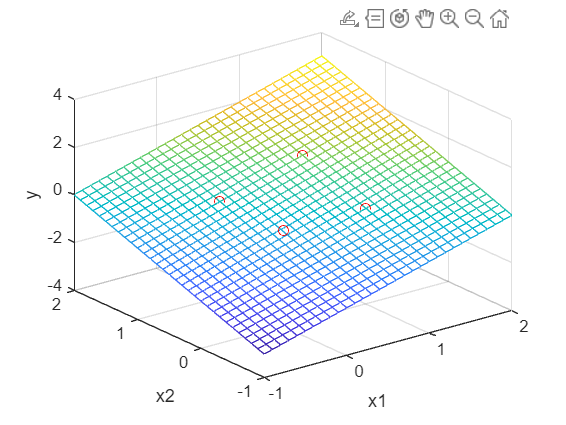

[X1, X2] = meshgrid(-1:0.1:2, -1:0.1:2);
Y = 1 * X1 + 1 * X2 - 1;

mesh(X1, X2, Y)
xlabel('x1'), ylabel('x2'), zlabel('y')
grid on
hold on
x1=[0 0 1 1];
x2=[0 1 0 1];
y =[0 0 0 1];
plot3(x1, x2, y, 'or')
hold off

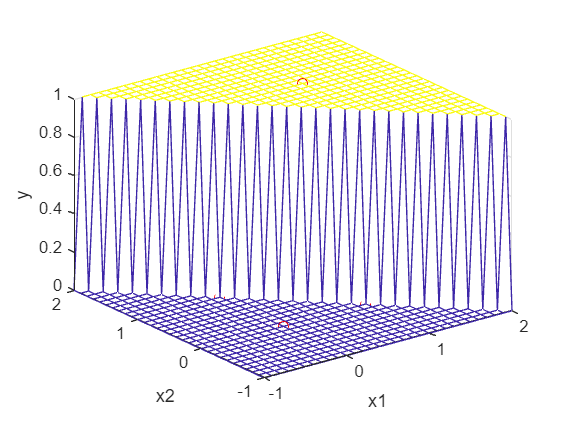


% Activation
Y(Y > 0) = 1;
Y(Y <= 0) = 0;

mesh(X1, X2, Y)
xlabel('x1'), ylabel('x2'), zlabel('y')
grid on
hold on
plot3(x1, x2, y, 'or')
hold off

## Exercise-2

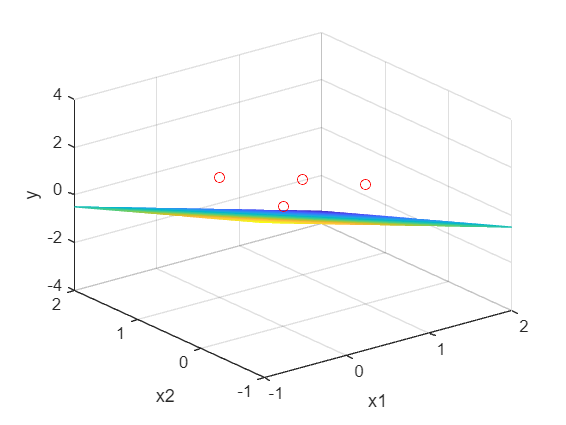

[X1, X2] = meshgrid(-1:0.1:2, -1:0.1:2);
Y = -1 * X1 + -1 * X2 + 0.5;

mesh(X1, X2, Y)
xlabel('x1'), ylabel('x2'), zlabel('y')
grid on
hold on
x1=[0 0 1 1];
x2=[0 1 0 1];
y =[1 1 1 0];
plot3(x1, x2, y, 'or')
hold off

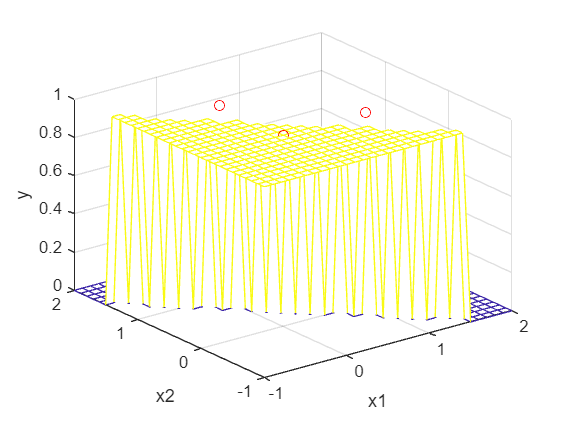


% Activation
Y(Y > 0) = 1;
Y(Y <= 0) = 0;

mesh(X1, X2, Y)
xlabel('x1'), ylabel('x2'), zlabel('y')
grid on
hold on
plot3(x1, x2, y, 'or')
hold off

## Exercise-3

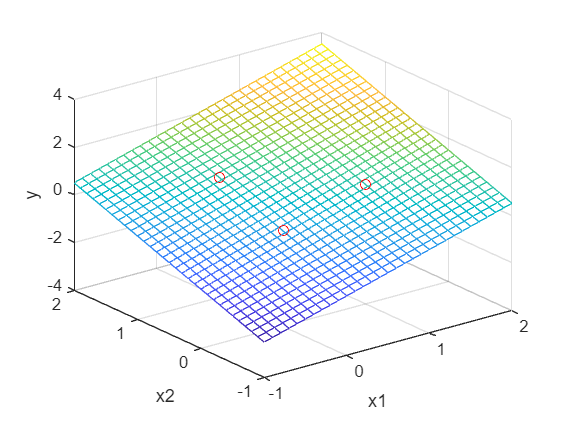

[X1, X2] = meshgrid(-1:0.1:2, -1:0.1:2);
Y = 1 * X1 + 1 * X2 - 0.5;

mesh(X1, X2, Y)
xlabel('x1'), ylabel('x2'), zlabel('y')
grid on
hold on
x1=[0 0 1 1];
x2=[0 1 0 1];
y =[0 1 1 1];
plot3(x1, x2, y, 'or')
hold off

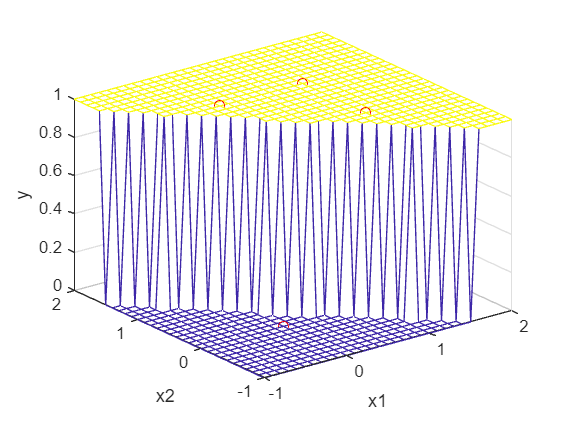


% Activation
Y(Y > 0) = 1;
Y(Y <= 0) = 0;

mesh(X1, X2, Y)
xlabel('x1'), ylabel('x2'), zlabel('y')
grid on
hold on
plot3(x1, x2, y, 'or')
hold off

## Exercise-4-1

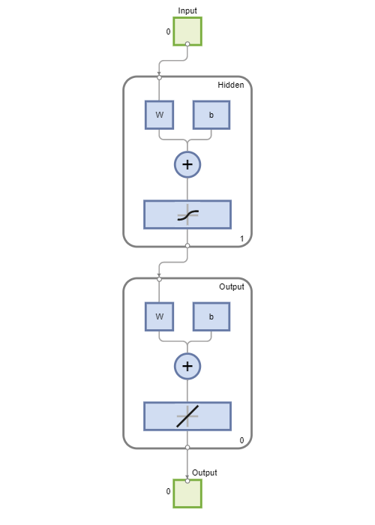

net = feedforwardnet(1);
view(net);

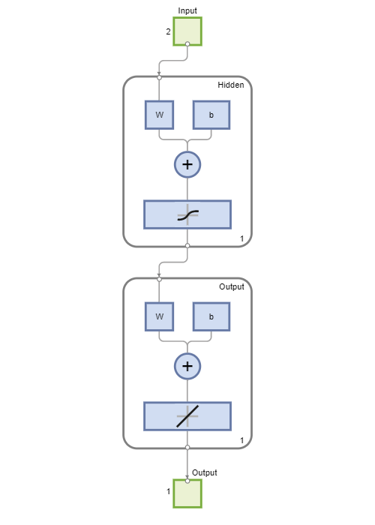


a = [0 0 1 1];
b = [0 1 0 1];
c = [0 1 1 0];

n = 600;

x = zeros(2, n);
y = zeros(1, n);

for k = 1:n
    j = randi([1 4]);
    x(:, k) = [a(j); b(j)];
    y(k) = c(j);
end

net = configure(net, x, y);
view(net);

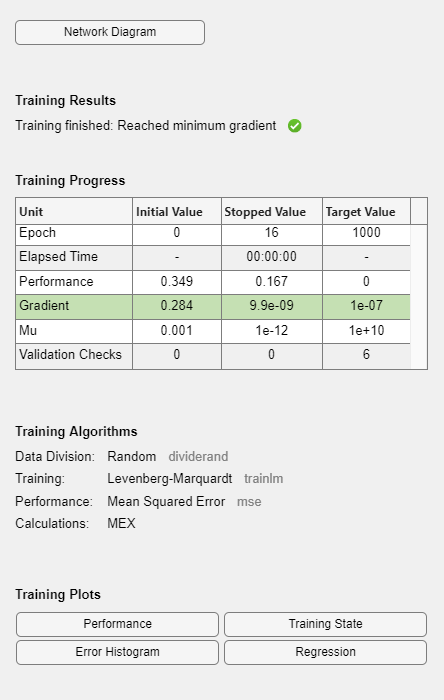

net.name = 'XOR';
net = train(net, x, y);


% 只有一個 neuron 無法正確分類 XOR
c = sim(net, [a;b])

c =     0.0000    0.6688    0.6688    0.6688


## Exercise-4-2

net = feedforwardnet([2 2]);
view(net);

a = [0 0 1 1];
b = [0 1 0 1];
c = [0 1 1 0];

n = 600;

x = zeros(2, n);
y = zeros(1, n);

for k = 1:n
    j = randi([1 4]);
    x(:, k) = [a(j); b(j)];
    y(k) = c(j);
end

net = configure(net, x, y);
view(net);
net.name = 'XOR';
net = train(net, x, y);

% 可以正確分類 XOR
c = sim(net, [a;b])

c =    -0.0000    1.0000    1.0000    0.0000
